# Linear Regression

## Data

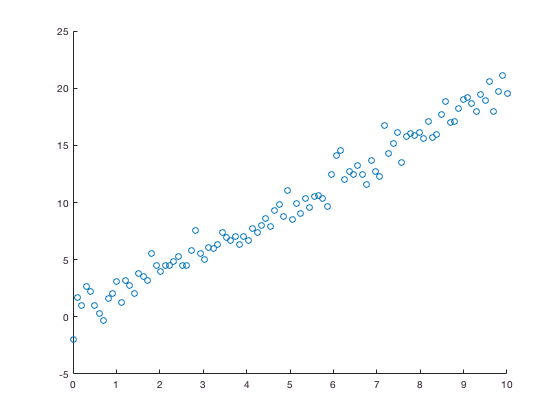

x = linspace(0, 10, 100)';
y = 2 * x + randn(size(x));
scatter(x, y)

## Least Square


$$S=\sum_{i=1}^n r_i^2$$



$$r_i=y_i-f\left(x_i,\theta\right)$$


A = [ones(size(x)), x];
theta = pinv(A) * y;
a = theta(1)

a = -0.0924

b = theta(2)

b = 2.0011

y_ = a + b * x;
error = ((y - y_)' * (y - y_)) / length(x)

error = 0.9919

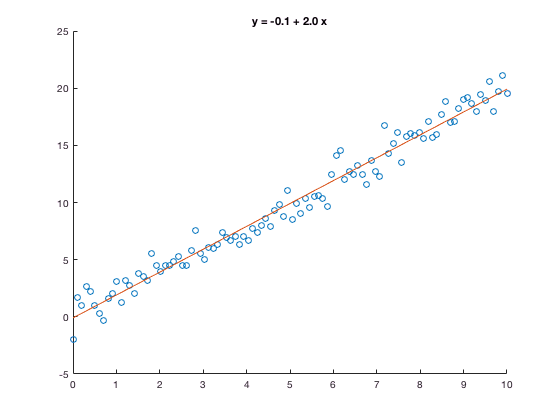

figure();
scatter(x, y);
hold('on');
plot(x, y_);
title(sprintf('y = %.1f + %.1f x', a, b));
hold('off');

## Correlation Coefficient


$$\hat{\beta}=r_{xy}\frac{s_y}{s_x}$$



$$\hat{\alpha}=\bar{y}-\hat{\beta}\bar{x}$$


corr_xy = corr(x, y);
std_x = std(x);
std_y = std(y);
mean_x = mean(x);
mean_y = mean(y);
b = corr_xy * std_y / std_x

b = 2.0011

a = mean_y - b * mean_x

a = -0.0924

y_ = a + b * x;
error = ((y - y_)' * (y - y_)) / length(x)

error = 0.9919

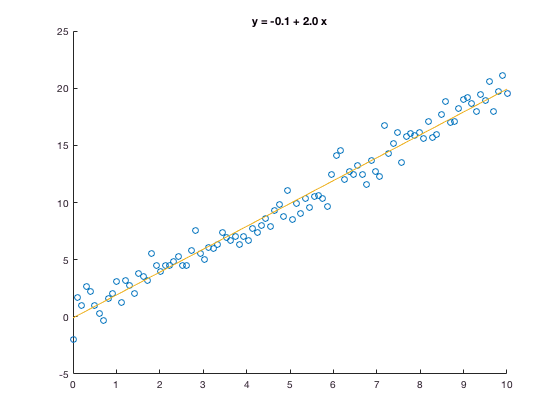

hold('on');
plot(x, y_);
title(sprintf('y = %.1f + %.1f x', a, b));
hold('off');

## Matlab

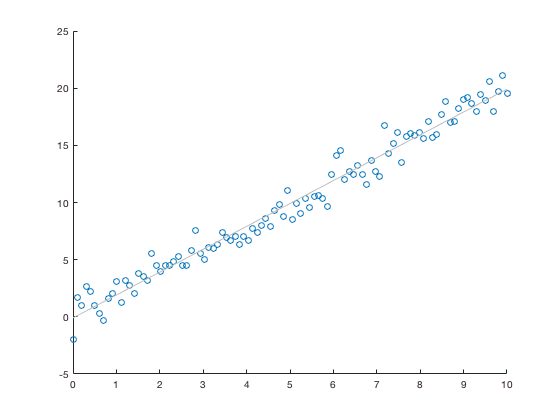

figure();
scatter(x, y);
lsline();

X = [ones(size(x)), x];
b = regress(y, X)

b =    -0.0924
    2.0011
